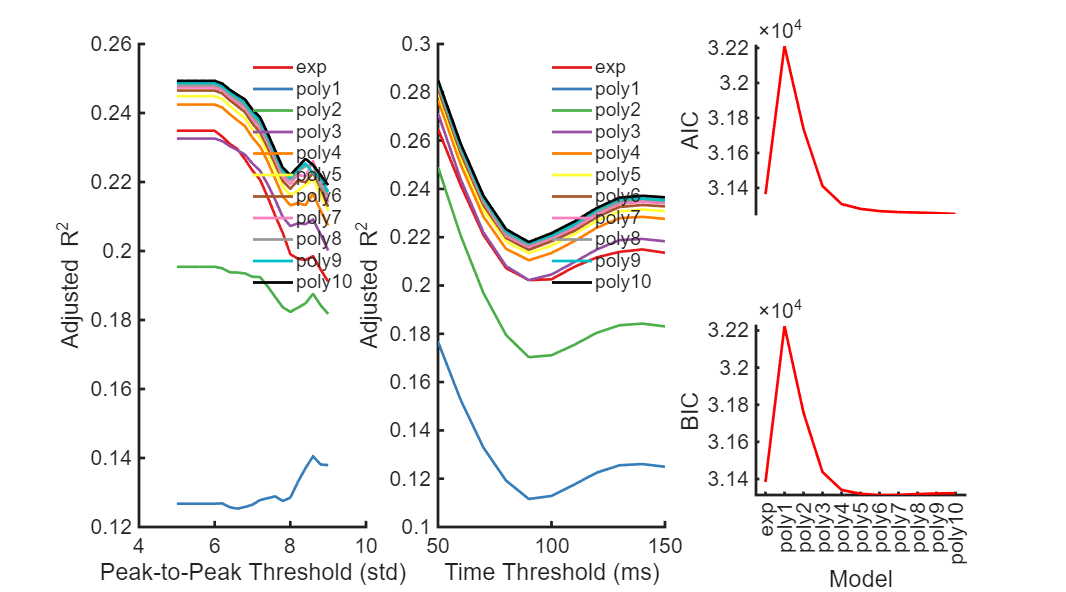

clc; clear; close all; addpath z_toolbox;
addpath E:\IEDpropagation\z_toolbox\Violinplot;
Path = 'step3_IEDtravelingWave';
load(fullfile(Path, 'IEDtw_ED-vs-delay_rate-vs-delay_diff-TD_diff-IL_fitting.mat'));
TD = 5:0.2:9; IL = (0.5:0.1:1.5).*100;
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
colors = [ 228  26  28; 55 126 184;
         77 175  74; 152  78 163;
        255 127   0; 255 255  51;
        166  86  40; 247 129 191;
        153 153 153; 0 191 196;
          0   0   0] / 255;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
modelStr = {'exp', 'poly1', 'poly2', 'poly3', 'poly4', 'poly5', ...
    'poly6', 'poly7', 'poly8', 'poly9', 'poly10'};
ED_delay_R2_exp = ED_delay_fit.R2adj_exp;
for nTD = 1:length(TD)
    A = squeeze(ED_delay_R2_exp(:, :, nTD));
    A(A<0) = [];
    ED_delay_R2_diffTD_mean(nTD, 1) = mean(A(:));
end
ED_delay_R2_poly = ED_delay_fit.R2adj_poly;
for n = 1:10
    for nTD = 1:length(TD)
        A = squeeze(ED_delay_R2_poly(:, :, nTD, n));
        A(A < 0) = [];
        ED_delay_R2_diffTD_mean(nTD, n + 1) = mean(A(:));
    end
end
subplot(2, 3, [1, 4]);
for n = 1:11
    plot(TD, ED_delay_R2_diffTD_mean(:, n), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', colors(n, :)); 
    hold on;
end
hold off; legend(modelStr, 'Box', 'off');
xlabel('Peak-to-Peak Threshold (std)');
ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for nIL = 1:length(IL)
    A = squeeze(ED_delay_R2_exp(:, nIL, :));
    A(A<0) = [];
    ED_delay_R2_diffIL_mean(nIL, 1) = mean(A(:));
end
for n = 1:10
    for nIL = 1:length(IL)
        A = squeeze(ED_delay_R2_poly(:, nIL, :, n));
        A(A<0) = [];
        ED_delay_R2_diffIL_mean(nIL, n + 1) = mean(A(:));
    end
end
subplot(2, 3, [2, 5]);
for n = 1:11
    plot(IL, ED_delay_R2_diffIL_mean(:, n), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', colors(n, :)); 
    hold on;
end
hold off;
legend(modelStr, 'Box', 'off');
xlabel('Time Threshold (ms)');
ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ax = subplot(2, 3, 3);
ED_delay_AIC_diffModel(:, 1) = ED_delay_fit.AIC_exp(:, 6, 6);
ED_delay_AIC_diffModel(:, 2:11) = squeeze(ED_delay_fit.AIC_poly(:, 6, 6, :));
x = 1:size(ED_delay_AIC_diffModel, 2);
plot(x, mean(ED_delay_AIC_diffModel, 1), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', [1, 0, 0]); 
ylabel('AIC'); ax.XColor = 'none';
xlim([0.5, 11.5]);
set(gca, 'XTick', [], 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2, 3, 6);
ED_delay_BIC_diffModel(:, 1) = ED_delay_fit.BIC_exp(:, 6, 6);
ED_delay_BIC_diffModel(:, 2:11) = squeeze(ED_delay_fit.BIC_poly(:, 6, 6, :));
x = 1:size(ED_delay_BIC_diffModel, 2);
plot(x, mean(ED_delay_BIC_diffModel, 1), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', [1, 0, 0]); 
xticks(x); xticklabels(modelStr);
xlabel('Model'); ylabel('BIC');
xlim([0.5, 11.5]); 
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);